# 1.

Es ist wichtig anzumerken das bei mehrfachem ausführen evtl. die Workspace variablen verwendet werden wodurch das ergebnis verzert wird. Fix: Workspace clearen.

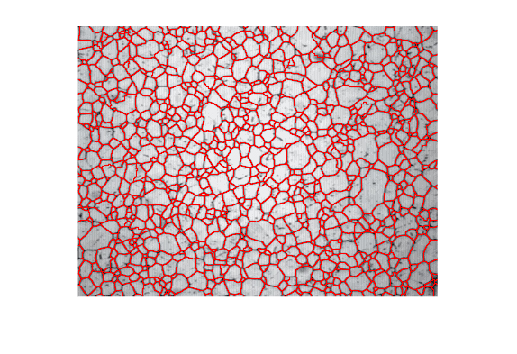

clear
% a)
img = imread("grains.jpg");
g_img = rgb2gray(img);
background = imhmin(imcomplement(g_img), 30);
waters = watershed(background);
% b)
segmented_image = imoverlay(img, waters == 0, 'red');
figure;
imshow(segmented_image);

% c) 
% Watershed markiert die einzelnen Pixel inerhalb von den segmenten von
% 1..n wobei n die Anzahl der Segmente ist, dementsprechend müssen erhalten
% wir die anzahl indem wir den maximalwert von der watershed matrix
% auslesen.
segment_anzahl = max(waters(:));
disp(['Anzahl der Segmente: ' num2str(segment_anzahl)]);

Anzahl der Segmente: 976


% d)
% Alle 0 werte in watershed
disp(['Anzahl der Pixel der Wasserscheiden: ' num2str(histcounts(waters(:), [0, 0]))]);

Anzahl der Pixel der Wasserscheiden: 21805


% e)
segment_ids = unique(waters);
segment_pixels = histcounts(waters(:), max(segment_ids) + 1);
[val, idx] = max(segment_pixels(2:end));
disp(['Das größte Segment hat ', num2str(val), ' Pixel.']);

Das größte Segment hat 1137 Pixel.


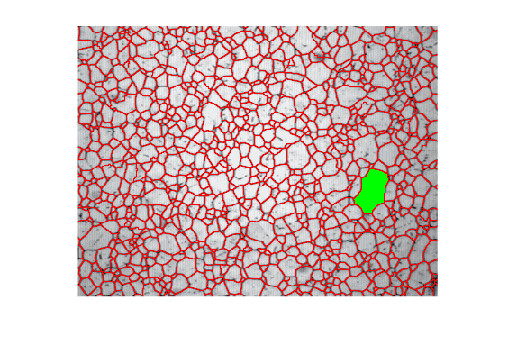

% f)
largest_segment = imoverlay(segmented_image, waters == idx, 'green');
figure;
imshow(largest_segment);

## 2.

Im vorschaubild sind die Trennlinien nicht so gut als durchgehend zu erkennen wenn man das Bild allerdings vergrößert passt es.

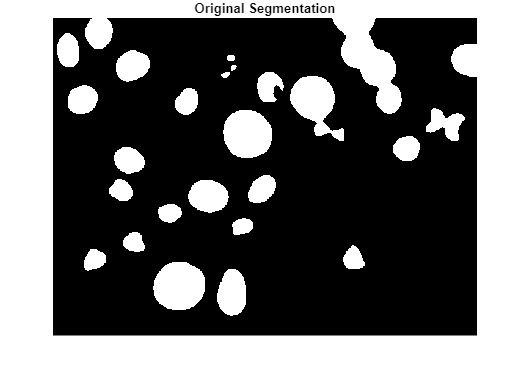

image = imread('ifm.jpg');
segmentation = imread('ifm_seg.png');
dist = bwdist(~segmentation);
dist = imhmin(imcomplement(dist), 1);
water = watershed(dist);
water(~segmentation) = 0;
overlay = imoverlay(segmentation, water == 0, 'black');
figure;
imshow(segmentation)
title('Original Segmentation')

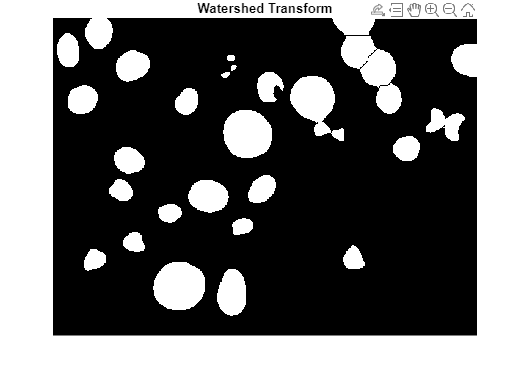

figure;
imshow(overlay)
title('Watershed Transform')